filenameVRS = "C:\Users\silva.LSMEDIT\Documents\sciebo\ProjektSeminar\dataset\subject1\stage1\imgV2.mat";
load(filenameVRS);
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');

% Organize the data into "snapshots": spatial is rows, time is columns
stdMap = std(imgV2,[],3);
imgV2(stdMap < max(stdMap(:)) * 0.25) = 0;
flatV = reshape(imgV2(:,:,1000:2000),32*32,[]);
X = flatV(:,1:end-1);
Y = flatV(:,2:end);

% Get rank reduced Koopman approximation
r = 100;
[U,S,V] = svd(X,'econ');
Ur = U(:,1:r);
Sr = S(1:r,1:r);
Vr = V(:,1:r);
Atilde = Ur'*Y*Vr/Sr;

% Get modes, amplitudes and dynamics
dt = 1/50;
[W,D] = eig(Atilde);

% Phi
Phi = Y*Vr/Sr*W;

% Lambda
d = diag(D);
lambda = log(d)/dt;

% Dynamics
b = Phi\X(:,1);
nModes = size(X,2);
time_dynamics = zeros(r, nModes);
t = (0:nModes-1) * dt;
for k = 1:nModes
    time_dynamics(:, k) = (b.*exp(lambda*t(k)));
end

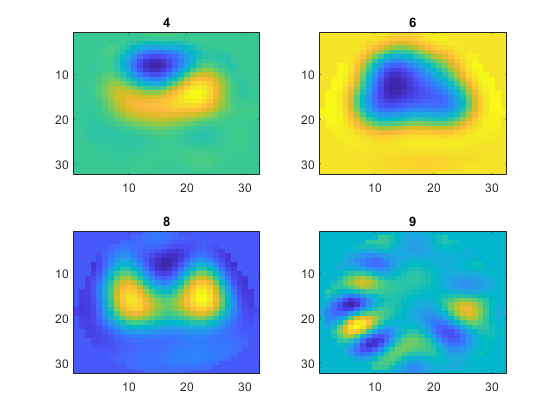

% Approximate low-rank Koopman operator
Atilde = Ur' * Y * Vr / Sr;

% Get eigenvalues and eigenvectors
[W,D] = eig(Atilde);
lambda = diag(D);

% Remove repeated conjugate pairs
uniqueIdx = (imag(lambda) >= 0);
% Calculate DMD modes and amplitudes (seen in absolute)
tmp = Y * Vr / Sr;
Phi = zeros(1024,r);
for i = 1:r
    Phi(:,i) = 1/lambda(i) * tmp * W(:,i);
end
b = inv(D) / Phi * X(:,2);

figure; 
subplot(2,2,1)
imagesc(reshape(real(Phi(:,3)),32,32)); title('4');

subplot(2,2,2)
imagesc(reshape(real(Phi(:,5)),32,32)); title('6');

subplot(2,2,3)
imagesc(reshape(real(Phi(:,7)),32,32)); title('8');

subplot(2,2,4)
imagesc(reshape(real(Phi(:,9)),32,32)); title('9');

% Reconstruct data (discrete)
Tmax = size(X1,2);
Xcomps = cell(r,1);
Xfinal = zeros(1024,Tmax);
for k = 1:Tmax
    for j = 1:r
        tmp = lambda(j)^(k-1) * b(j) * Phi(:,j);
        Xcomps{j}(:,k) = tmp;
        Xfinal(:,k) = Xfinal(:,k) + tmp;
    end
end

% Reconstruct data (continuous)
fs = 50;
dt = 1/fs;

xcomps = cell(r,1);
xfinal = zeros(1024,Tmax);
omega = log(lambda)/dt;

t = (0:Tmax - 1) * dt;
for k = 1:Tmax
    for j = 1:r
        tmp =  Phi(:,j) * b(j) * exp(omega(j) * t(k));
        xcomps{j}(:,k) = tmp;
        xfinal(:,k) = xfinal(:,k) + tmp;
    end
end

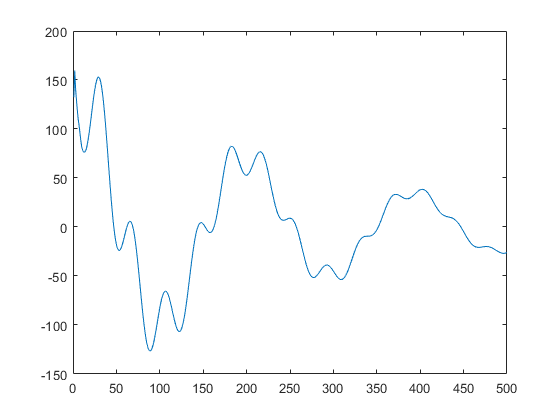

heartPix = [7,15];
lungPix = [14,22];

heartSig = real(reshape(Xcomps{7},32,32,Tmax));
totalSig = real(reshape(Xfinal,32,32,Tmax));
figure; plot(squeeze(totalSig(heartPix(1),heartPix(2),:)));

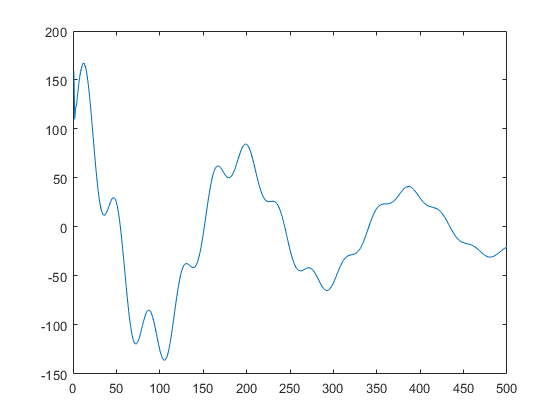


figure; plot(squeeze(totalSig(lungPix(1),lungPix(2),:)));

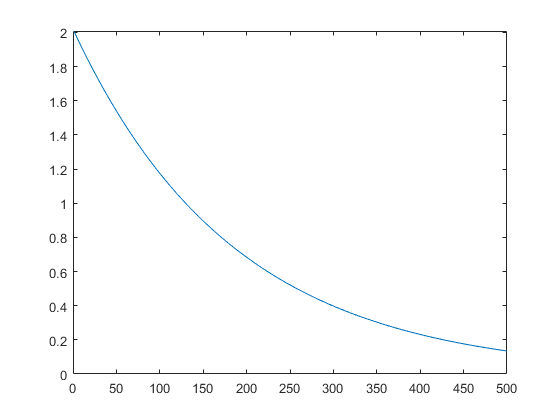


figure; plot(squeeze(heartSig(heartPix(1),heartPix(2),:)));

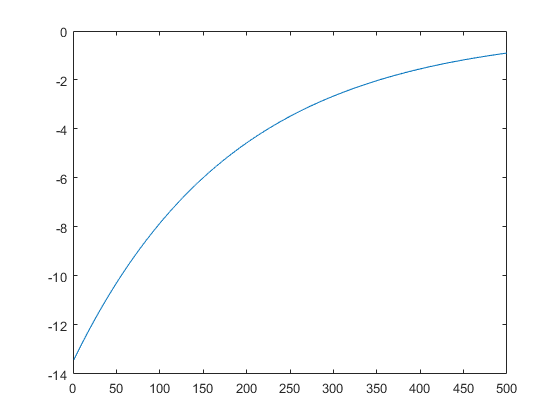


figure; plot(squeeze(heartSig(lungPix(1),lungPix(2),:)));

heartPix = [7,15];
lungPix = [14,22];

heartSig = real(reshape(xcomps{4},32,32,Tmax));
totalSig = real(reshape(xfinal,32,32,Tmax));
figure; plot(squeeze(totalSig(heartPix(1),heartPix(2),:)));

figure; plot(squeeze(totalSig(lungPix(1),lungPix(2),:)));

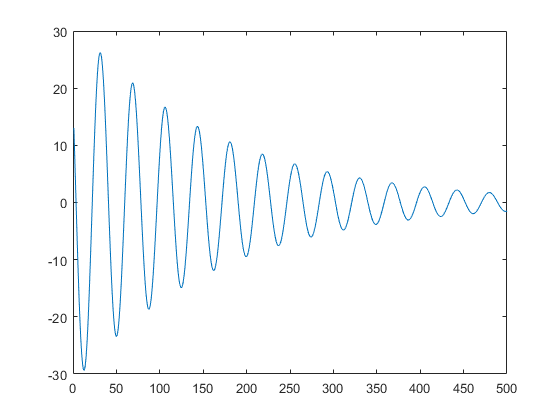


figure; plot(squeeze(heartSig(heartPix(1),heartPix(2),:)));

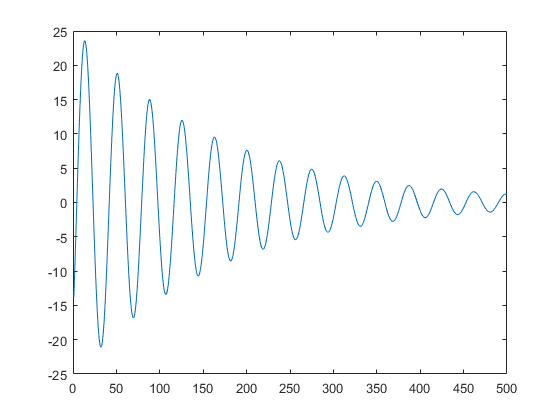

figure; plot(squeeze(heartSig(lungPix(1),lungPix(2),:)));

% Remove repeated pairs
r0 = sum(uniqueIdx);
lambda = lambda(uniqueIdx);
Phi = Phi(:, uniqueIdx);
b = b(uniqueIdx);

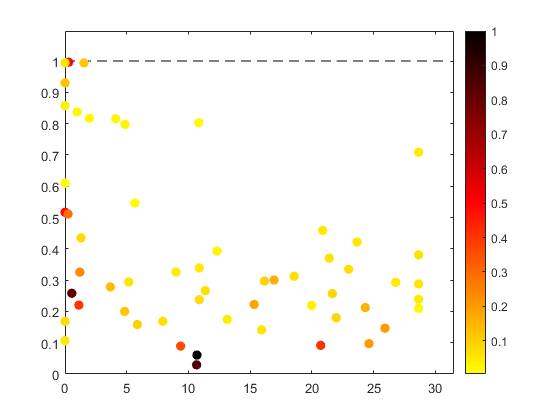

% magnitude vs frequency plot
norms = abs(b' .* vecnorm(Phi,2,1)); norms = norms / max(norms);
mag = abs(lambda);
freq = 180 * angle(lambda)/(2 * pi ^ 2);
freqRef = 0:(1.1 * max(freq));
figure; plot(freqRef, ones(size(freqRef)), 'LineStyle','--','Color','k'); 
hold on; scatter(freq, mag, 50 * ones(size(freq)), norms, 'filled', 'Marker','o'); colorbar; colormap(perfCm); 
ylim([0 1.1 * max(mag)]); xlim([0 1.1 * max(freq)]);

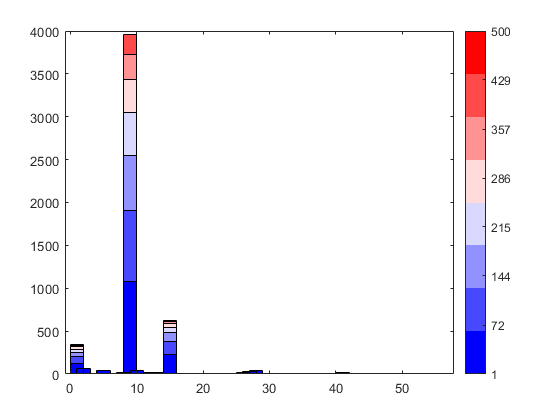

% Dominance structure plot
cm = barCm(round(linspace(1,256,nDivs)),:);

dom = zeros(r0,Tmax);
for k = 1:Tmax
    for j = 1:r0
        dom(j,k) = norm(lambda(j)^(k-1) * b(j) * Phi(:,j));
    end
end

nDivs = 8;
divs = round(linspace(1,Tmax,nDivs));
finalDom = zeros(r0,nDivs);
for j = 1:r0
    for i = 1:nDivs-1
        finalDom(j,i) = sum(dom(j,divs(i):divs(i + 1)),2)./(divs(i + 1) - divs(i));
    end
end

[~, idx] = sort(freq);
figure; ba = bar(finalDom(idx,:),'stacked', 'FaceColor','flat');
for i = 1:nDivs-1
    ba(i).CData = cm(i,:);
    ba(i).BarWidth = 2;
%     ba(i).XData = freq;
end
colormap(cm); cb = colorbar; 
caxis([divs(1),divs(end)]);
set(cb,'Ticks',divs(1:end))

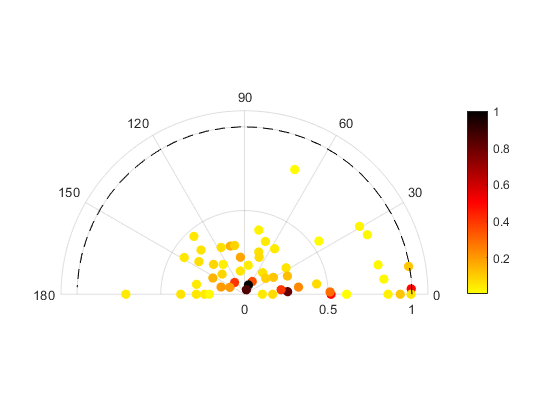

% Nyquist Plot
cm = perfCm(round(linspace(1,256,length(freq))),:);
freqRef = 0:0.1:pi;

figure; p = polarscatter(phase(lambda),abs(lambda), 50 * ones(size(freq)), norms,'filled');
thetalim([0 180]); rlim([0 1.1 * max(mag)]);
colorbar; colormap(perfCm); 
hold on; polarplot(freqRef, ones(size(freqRef)), 'k--');